## Задание 1. Задача стабилизации с идеальным дифференцирующим звеном

mdl = "task_1";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);

a2=1;a1=-3;a0=2;
iy=1; idy=-2;
k0=0;k1=0;

res = sim(simIn);

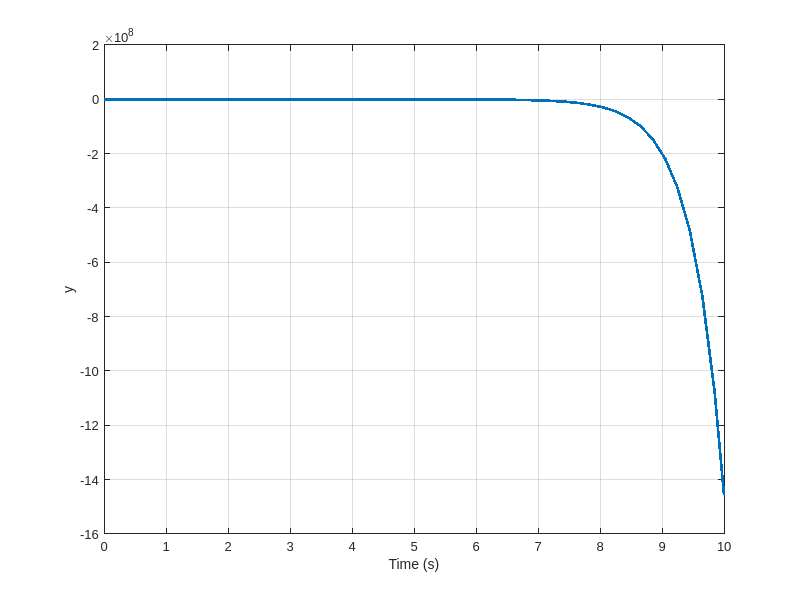

figure('Position', [0 0 800 600]);
sig = res.get('yout');
t = sig{1}.Values.Time;
y = sig{1}.Values.Data;
plot(t, y, 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('y');
exportgraphics(gcf, 'figs/task_1_out.png', 'Resolution', 300);

mdl = "task_1";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);

a2=1;a1=-3;a0=2;
iy=1; idy=-2;
k0=1;k1=-4;

res = sim(simIn);

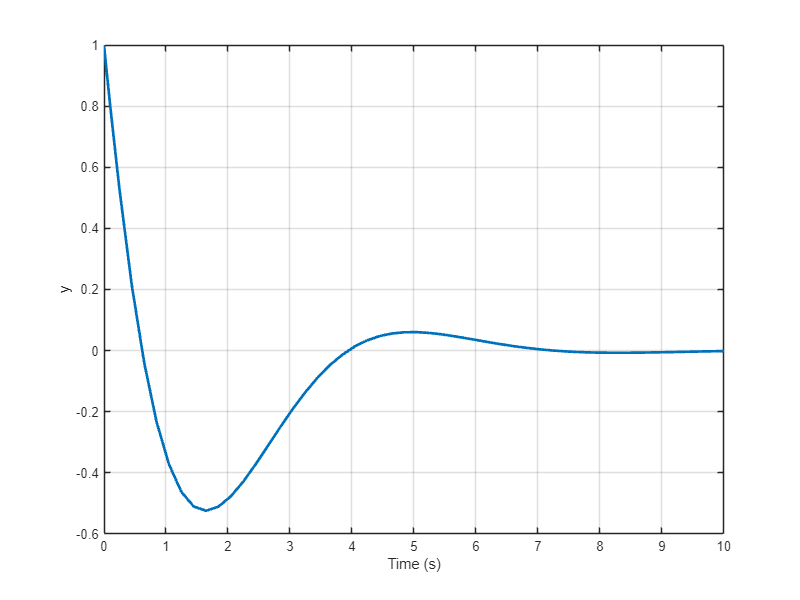

figure('Position', [0 0 800 600]);
sig = res.get('yout');
t_perf = sig{1}.Values.Time;
y_perf = sig{1}.Values.Data;
plot(t_perf, y_perf, 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('y');
exportgraphics(gcf, 'figs/task_1_out_1.png', 'Resolution', 300);

## Задание 2. Задача стабилизации с реальным дифференцирующим звеном

mdl = "task_2";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);

a2=1;a1=-3;a0=2;
iy=1; idy=-2;
k0=1;k1=-4;

T=0.001;
res21 = sim(simIn);
T=0.1;
res22 = sim(simIn);
T=0.2;
res23 = sim(simIn);

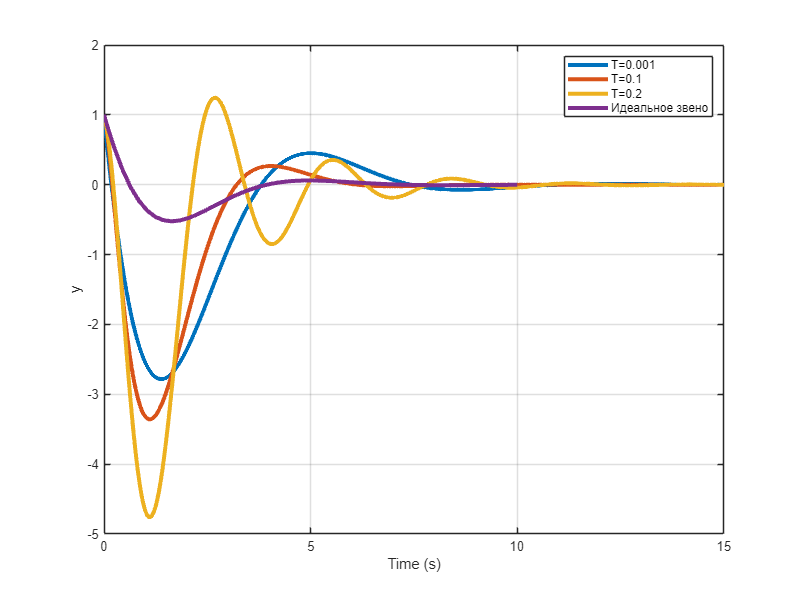

figure('Position', [0 0 800 600]);

sig1 = res21.get('yout');
sig2 = res22.get('yout');
sig3 = res23.get('yout');

t1 = sig1{1}.Values.Time;
t2 = sig2{1}.Values.Time;
t3 = sig3{1}.Values.Time;

y1 = sig1{1}.Values.Data;
y2 = sig2{1}.Values.Data;
y3 = sig3{1}.Values.Data;

plot(t1, y1, 'LineWidth', 3); hold on;
plot(t2, y2, 'LineWidth', 3);
plot(t3, y3, 'LineWidth', 3);
plot(t_perf, y_perf, 'LineWidth', 3); hold off;

legend('T=0.001', 'T=0.1', 'T=0.2', 'Идеальное звено');
grid on;
xlabel('Time (s)');
ylabel('y');
exportgraphics(gcf, 'figs/task_2_out.png', 'Resolution', 300);

## Задания 3. Задача слежения для системы с астатизмом нулевого порядка

mdl = "task_3";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);

A=1;

k=-1/4;
res31 = sim(simIn);
k=5;
res32 = sim(simIn);
k=10;
res33 = sim(simIn);

figure('Position', [0, 0, 900, 600]);

sig1 = res31.get('yout');
sig2 = res32.get('yout');
sig3 = res33.get('yout');

t1 = sig1{1}.Values.Time;
t2 = sig2{1}.Values.Time;
t3 = sig3{1}.Values.Time;

y1 = sig1{1}.Values.Data;
y2 = sig2{1}.Values.Data;
y3 = sig3{1}.Values.Data;

subplot(2, 1, 1)

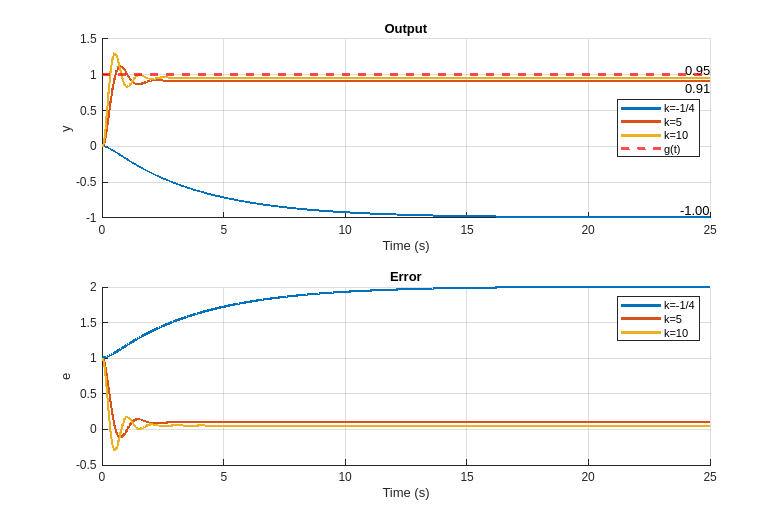


yline(1, 'r--', 'LineWidth', 2); hold on;
plot(t1, y1, 'LineWidth', 2);
plot(t2, y2, 'LineWidth', 2);
plot(t3, y3, 'LineWidth', 2);

legend('g(t)', 'k=-1/4', 'k=5', 'k=10', 'Location', 'east');
grid on;
xlabel('Time (s)');
ylabel('y');
title('Output');

% Calculate the final values for each plot
y_final1 = y1(end);
y_final2 = y2(end);
y_final3 = y3(end);

% Annotate final values on the plot
text(t1(end), y_final1, sprintf('%.2f', y_final1), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
text(t2(end), y_final2, sprintf('%.2f', y_final2), 'VerticalAlignment', 'top', 'HorizontalAlignment', 'right');
text(t3(end), y_final3, sprintf('%.2f', y_final3), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

subplot(2, 1, 2)

hold on;
plot(t1, 1-y1, 'LineWidth', 2);
plot(t2, 1-y2, 'LineWidth', 2);
plot(t3, 1-y3, 'LineWidth', 2);

legend('k=-1/4', 'k=5', 'k=10');
grid on;
xlabel('Time (s)');
ylabel('e');
title('Error');

exportgraphics(gcf, 'figs/task_3_out.png', 'Resolution', 300);

mdl = "task_3_1";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);

V=2;

k=-1/4;
res31 = sim(simIn);
k=5;
res32 = sim(simIn);
k=10;
res33 = sim(simIn);

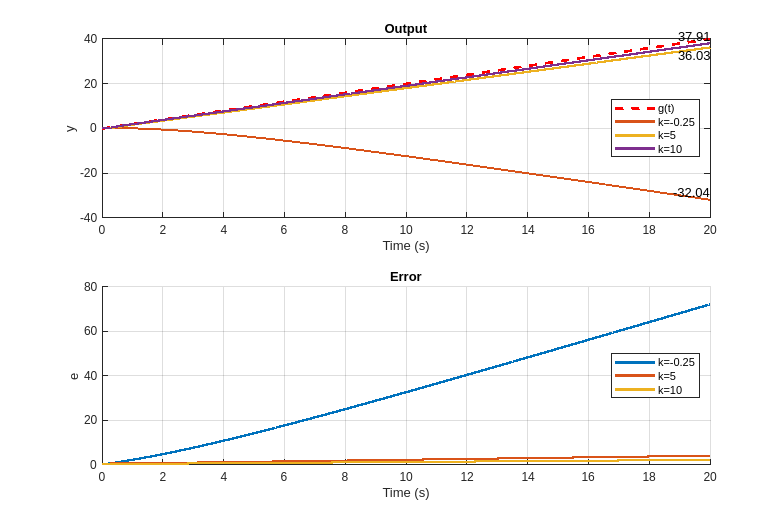

figure('Position', [0, 0, 900, 600]);

sig1 = res31.get('yout');
sig2 = res32.get('yout');
sig3 = res33.get('yout');

t1 = sig1{1}.Values.Time;
t2 = sig2{1}.Values.Time;
t3 = sig3{1}.Values.Time;

y1 = sig1{1}.Values.Data;
y2 = sig2{1}.Values.Data;
y3 = sig3{1}.Values.Data;

subplot(2, 1, 1)

plot(t1, t1*V, 'r--', 'LineWidth', 2); hold on;
plot(t1, y1, 'LineWidth', 2);
plot(t2, y2, 'LineWidth', 2);
plot(t3, y3, 'LineWidth', 2);

legend('g(t)', 'k=-0.25', 'k=5', 'k=10', 'Location', 'east');
grid on;
xlabel('Time (s)');
ylabel('y');
title('Output');

% Calculate the final values for each plot
y_final1 = y1(end);
y_final2 = y2(end);
y_final3 = y3(end);

% Annotate final values on the plot
text(t1(end), y_final1, sprintf('%.2f', y_final1), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
text(t2(end), y_final2, sprintf('%.2f', y_final2), 'VerticalAlignment', 'top', 'HorizontalAlignment', 'right');
text(t3(end), y_final3, sprintf('%.2f', y_final3), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

subplot(2, 1, 2)

hold on;
plot(t1, t1*V-y1, 'LineWidth', 2);
plot(t2, t2*V-y2, 'LineWidth', 2);
plot(t3, t3*V-y3, 'LineWidth', 2);

legend('k=-0.25', 'k=5', 'k=10', 'Location', 'east');
grid on;
xlabel('Time (s)');
ylabel('e');
title('Error');

exportgraphics(gcf, 'figs/task_3_out_1.png', 'Resolution', 300);

## Задание 4. Задача слежения для системы с астатизмом первого порядка (И-регулятор)

function signal = generate_signal(type, t, A, V, a)
    switch type
        case 'constant'
            signal = A * ones(size(t));
        case 'linear'
            signal = V * t;
        case 'quadratic'
            signal = 0.5 * a * t.^2;
        otherwise
            error('Unknown signal type');
    end
    signal = [t, signal]; % Формат для передачи в Simulink
end

mdl = "task_4";
open_system(mdl);

% Параметры
A = 1;
V = 2;
a = 0.4;
t_end = 50; % Установка времени симуляции
t = linspace(0, t_end, 1000)';

% Установка времени симуляции в Simulink
set_param(mdl, 'StopTime', num2str(t_end));

% Параметры для симуляции
signal_types = {'constant', 'linear', 'quadratic'};
k_values = [0.1, 0.5, 0.9];

% Генерация и сохранение графиков для каждого типа сигнала
for signal_idx = 1:length(signal_types)
    signal_type = signal_types{signal_idx};
    
    % Создаем сигнал и передаем его в Simulink
    simIn = Simulink.SimulationInput(mdl);
    simIn = simIn.setVariable('input_signal', generate_signal(signal_type, t, A, V, a));
    
    % Подготовка фигуры для графиков
    figure('Position', [0, 0, 900, 600]);
    
    % Инициализация массива для ошибок e(t)
    all_errors = cell(length(k_values), 1);
    
    % Симулируем систему для каждого значения k и сохраняем результаты
    for k_idx = 1:length(k_values)
        k = k_values(k_idx);
        simIn = simIn.setVariable('k', k); % Передача значения k в Simulink
        res = sim(simIn); % Запуск симуляции
        
        % Извлекаем данные
        sig = res.get('yout');
        time = sig{1}.Values.Time;
        y = sig{1}.Values.Data;
        
        % Расчет ошибки e(t) = g(t) - y(t)
        g = generate_signal(signal_type, time, A, V, a);
        e = g(:, 2) - y;
        all_errors{k_idx} = e; % Сохранение ошибки для графика

        % Подграфик выхода
        subplot(2, 1, 1);
        plot(time, y, 'LineWidth', 2);
        hold on;
    end
    
    % Построение ожидаемого сигнала на выходном графике
    subplot(2, 1, 1);
    plot(time, g(:, 2), 'r--', 'LineWidth', 2); % Ожидаемый сигнал g(t)
    if (signal_idx == 1)
        legend([arrayfun(@(k) sprintf('k = %.1f', k), k_values, 'UniformOutput', false), {'g(t)'}], 'Location', 'northeast');
    else
        legend([arrayfun(@(k) sprintf('k = %.1f', k), k_values, 'UniformOutput', false), {'g(t)'}], 'Location', 'east');
    end
    xlabel('Time (s)');
    ylabel('y(t)');
    title(['Output for ', signal_type, ' signal']);
    grid on;

    % Подграфик ошибки для каждого k
    subplot(2, 1, 2);
    hold on;
    for k_idx = 1:length(k_values)
        plot(time, all_errors{k_idx}, 'LineWidth', 2);
        if (signal_idx == 2)
            text(time(end), all_errors{k_idx}(end), sprintf('%.2f', all_errors{k_idx}(end)), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
        end
    end
    if (signal_idx == 1)
        legend(arrayfun(@(k) sprintf('Error for k = %.1f', k), k_values, 'UniformOutput', false), 'Location', 'northeast');
    else
        legend(arrayfun(@(k) sprintf('Error for k = %.1f', k), k_values, 'UniformOutput', false), 'Location', 'east');
    end
    xlabel('Time (s)');
    ylabel('Error e(t) = g(t) - y(t)');
    title(['Error for ', signal_type, ' signal']);
    grid on;
    
    % Сохранение графика
    exportgraphics(gcf, ['figs/task_4_out_' signal_type '.png'], 'Resolution', 300);
    close(gcf);
end

## Задание 5. Задача слежения для системы с астатизмом первого порядка (ПИ-регулятор)

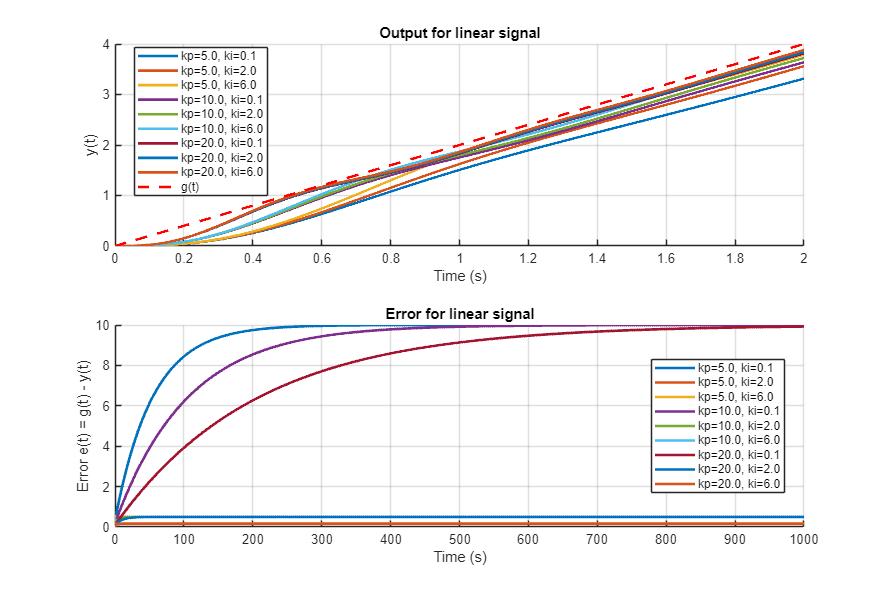

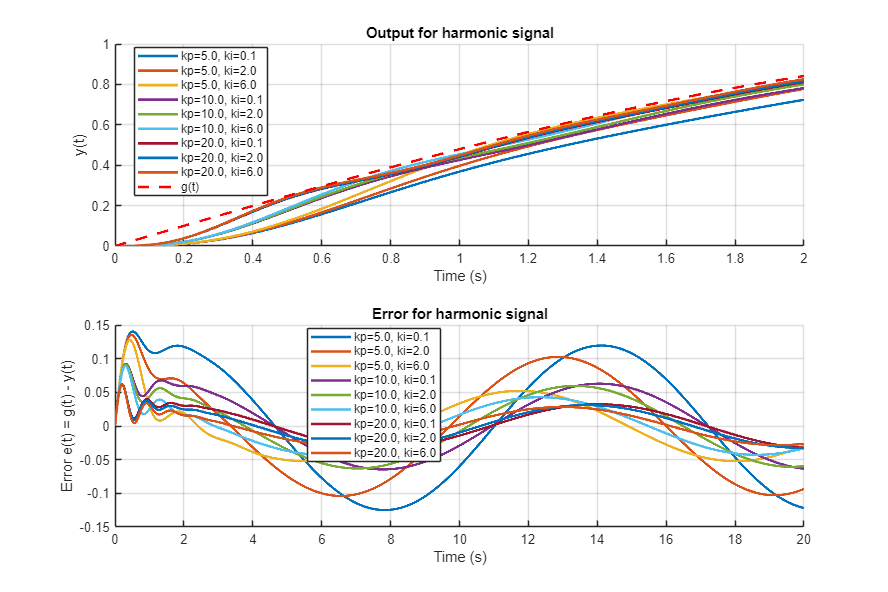

function signal = generate_signal1(type, t, A, V, omega)
    switch type
        case 'linear'
            signal = V * t;
        case 'harmonic'
            signal = A * sin(omega*t);
        otherwise
            error('Unknown signal type');
    end
    signal = [t, signal]; % Формат для передачи в Simulink
end

mdl = "task_5";
open_system(mdl);

% Параметры
A = 1;
V = 2;
omega=0.5;
t_end = 1000; % Установка времени симуляции
ts = linspace(0, t_end, 1000)';

% Параметры для симуляции
signal_types = {'linear', 'harmonic'};
kp_values = [5, 10, 20];
ki_values = [0.1, 2, 6];

% Подготовка таблицы для сохранения установившихся значений (для линейного сигнала)
steady_state_table = [];

% Генерация и сохранение графиков для каждого типа сигнала
for signal_idx = 1:length(signal_types)
    signal_type = signal_types{signal_idx};
    
    % Установка времени симуляции в зависимости от типа сигнала
    switch signal_type
        case 'linear'
            t_end = 1000; % Время для линейного сигнала
        case 'harmonic'
            t_end = 20; % Время для гармонического сигнала
    end
    ts = linspace(0, t_end, 1000)';

    % Установка времени симуляции в Simulink
    set_param(mdl, 'StopTime', num2str(t_end));

    % Создаем сигнал и передаем его в Simulink
    simIn = Simulink.SimulationInput(mdl);
    simIn = simIn.setVariable('input_signal', generate_signal1(signal_type, ts, A, V, omega));
    
    % Подготовка фигуры для графиков
    figure('Position', [0, 0, 900, 600]);
    
    % Цикл по всем комбинациям kp и ki
    legend_entries = {}; % Для легенды графиков
    for kp = kp_values
        for ki = ki_values
            % Передача значений kp и ki в Simulink
            simIn = simIn.setVariable('kp', kp);
            simIn = simIn.setVariable('ki', ki);
            
            % Запуск симуляции
            res = sim(simIn);
            
            % Извлекаем данные
            sig = res.get('yout');
            time = sig{1}.Values.Time;
            y = sig{1}.Values.Data;
            
            % Расчет ошибки e(t) = g(t) - y(t)
            g = generate_signal1(signal_type, time, A, V, omega);
            e = g(:, 2) - y; % Ошибка для второго графика
            
            % Построение графика выхода y(t)
            subplot(2, 1, 1);
            hold on;
            plot(time, y, 'LineWidth', 2);
            legend_entries{end+1} = sprintf('kp=%.1f, ki=%.1f', kp, ki); % Добавление подписи

            % Построение ошибки для второго графика
            subplot(2, 1, 2);
            hold on;
            plot(time, e, 'LineWidth', 2);

            % Добавление установившегося значения для линейного сигнала
            if strcmp(signal_type, 'linear')
                e_final = e(end);
                steady_state_table = [steady_state_table; kp, ki, e_final];
            end
        end
    end
    
    % Настройки для первого подграфика - выход y(t)
    subplot(2, 1, 1);
    plot(time, g(:, 2), 'r--', 'LineWidth', 2); % Ожидаемый сигнал g(t)
    legend([legend_entries, {'g(t)'}], 'Location', 'best');
    xlabel('Time (s)');
    ylabel('y(t)');
    title(['Output for ', signal_type, ' signal']);
    grid on;
    xlim([0, 2]);
    %ylim([0, 10]);
    
    % Настройки для второго подграфика - ошибка e(t)
    subplot(2, 1, 2);
    legend(legend_entries, 'Location', 'best');
    xlabel('Time (s)');
    ylabel('Error e(t) = g(t) - y(t)');
    title(['Error for ', signal_type, ' signal']);
    grid on;

    % Сохранение графика
    exportgraphics(gcf, ['figs/task_5_out_' signal_type '.png'], 'Resolution', 300);
end


% Отображение таблицы установившихся значений для линейного сигнала
steady_state_table = array2table(steady_state_table, 'VariableNames', {'kp', 'ki', 'e_final'});
disp('Steady-state values for linear input signal:');

Steady-state values for linear input signal:


disp(steady_state_table);

    kp    ki     e_final
    __    ___    _______

     5    0.1         10
     5      2        0.5
     5      6    0.16667
    10    0.1     9.9993
    10      2        0.5
    10      6    0.16667
    20    0.1     9.9247
    20      2        0.5
    20      6    0.16667



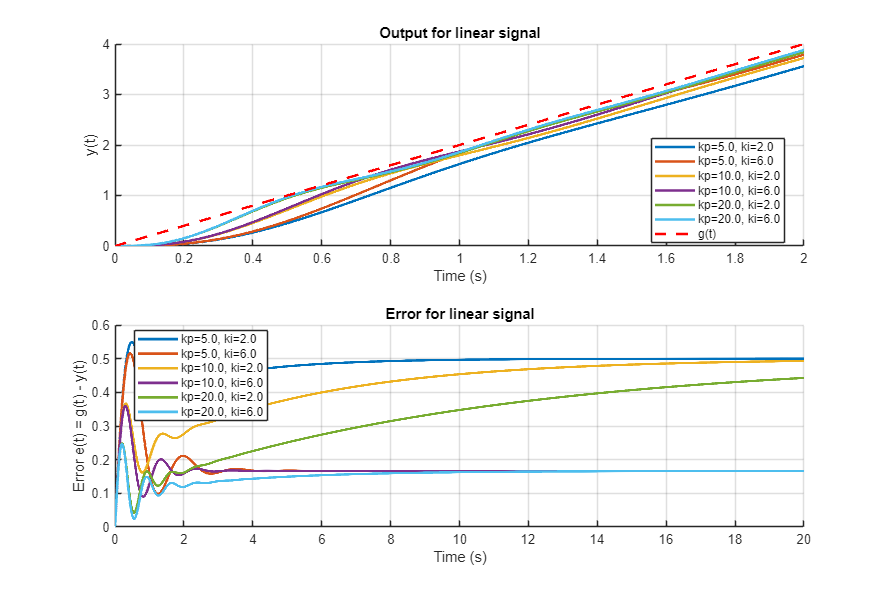

mdl = "task_5";
open_system(mdl);

% Параметры
A = 1;
V = 2;
omega=0.5;
t_end = 1000; % Установка времени симуляции
ts = linspace(0, t_end, 1000)';

% Параметры для симуляции
signal_types = {'linear'};
kp_values = [5, 10, 20];
ki_values = [2, 6];

% Подготовка таблицы для сохранения установившихся значений (для линейного сигнала)
steady_state_table = [];

% Генерация и сохранение графиков для каждого типа сигнала
for signal_idx = 1:length(signal_types)
    signal_type = signal_types{signal_idx};
    
    % Установка времени симуляции в зависимости от типа сигнала
    switch signal_type
        case 'linear'
            t_end = 20; % Время для линейного сигнала
        case 'harmonic'
            t_end = 20; % Время для гармонического сигнала
    end
    ts = linspace(0, t_end, 1000)';

    % Установка времени симуляции в Simulink
    set_param(mdl, 'StopTime', num2str(t_end));

    % Создаем сигнал и передаем его в Simulink
    simIn = Simulink.SimulationInput(mdl);
    simIn = simIn.setVariable('input_signal', generate_signal1(signal_type, ts, A, V, omega));
    
    % Подготовка фигуры для графиков
    figure('Position', [0, 0, 900, 600]);
    
    % Цикл по всем комбинациям kp и ki
    legend_entries = {}; % Для легенды графиков
    for kp = kp_values
        for ki = ki_values
            % Передача значений kp и ki в Simulink
            simIn = simIn.setVariable('kp', kp);
            simIn = simIn.setVariable('ki', ki);
            
            % Запуск симуляции
            res = sim(simIn);
            
            % Извлекаем данные
            sig = res.get('yout');
            time = sig{1}.Values.Time;
            y = sig{1}.Values.Data;
            
            % Расчет ошибки e(t) = g(t) - y(t)
            g = generate_signal1(signal_type, time, A, V, omega);
            e = g(:, 2) - y; % Ошибка для второго графика
            
            % Построение графика выхода y(t)
            subplot(2, 1, 1);
            hold on;
            plot(time, y, 'LineWidth', 2);
            legend_entries{end+1} = sprintf('kp=%.1f, ki=%.1f', kp, ki); % Добавление подписи

            % Построение ошибки для второго графика
            subplot(2, 1, 2);
            hold on;
            plot(time, e, 'LineWidth', 2);
        end
    end
    
    % Настройки для первого подграфика - выход y(t)
    subplot(2, 1, 1);
    plot(time, g(:, 2), 'r--', 'LineWidth', 2); % Ожидаемый сигнал g(t)
    legend([legend_entries, {'g(t)'}], 'Location', 'best');
    xlabel('Time (s)');
    ylabel('y(t)');
    title(['Output for ', signal_type, ' signal']);
    grid on;
    xlim([0, 2]);
    
    % Настройки для второго подграфика - ошибка e(t)
    subplot(2, 1, 2);
    legend(legend_entries, 'Location', 'best');
    xlabel('Time (s)');
    ylabel('Error e(t) = g(t) - y(t)');
    title(['Error for ', signal_type, ' signal']);
    grid on;

    % Сохранение графика
    exportgraphics(gcf, ['figs/task_5_out_1_' signal_type '.png'], 'Resolution', 300);
end

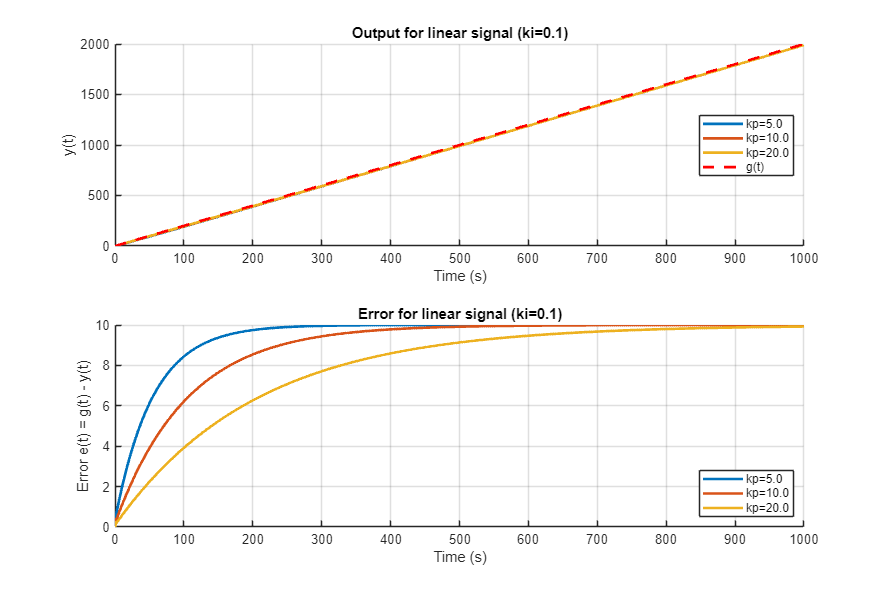

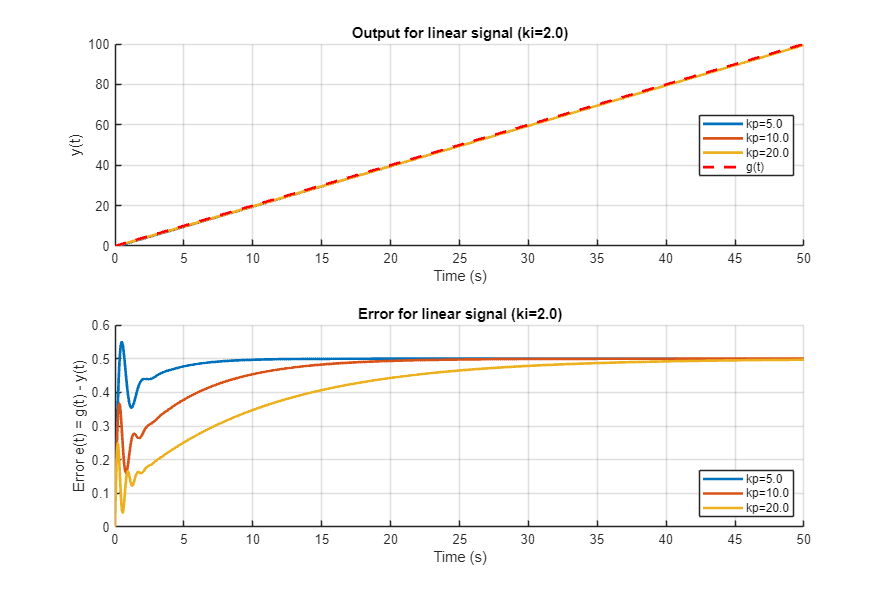

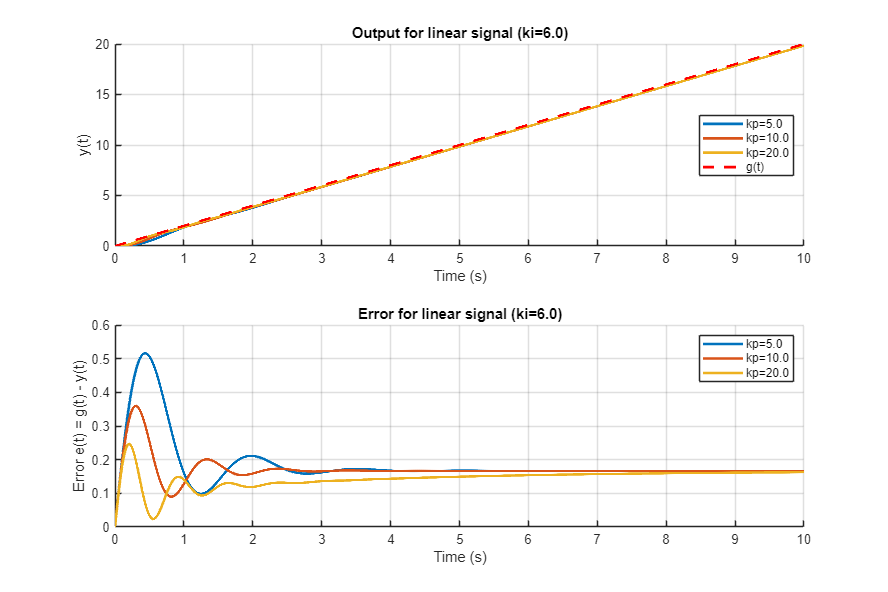

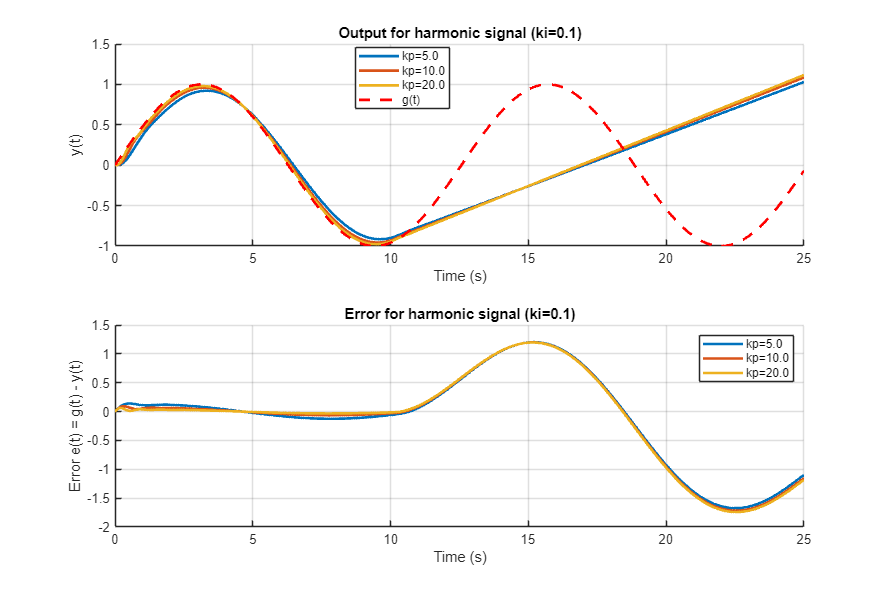

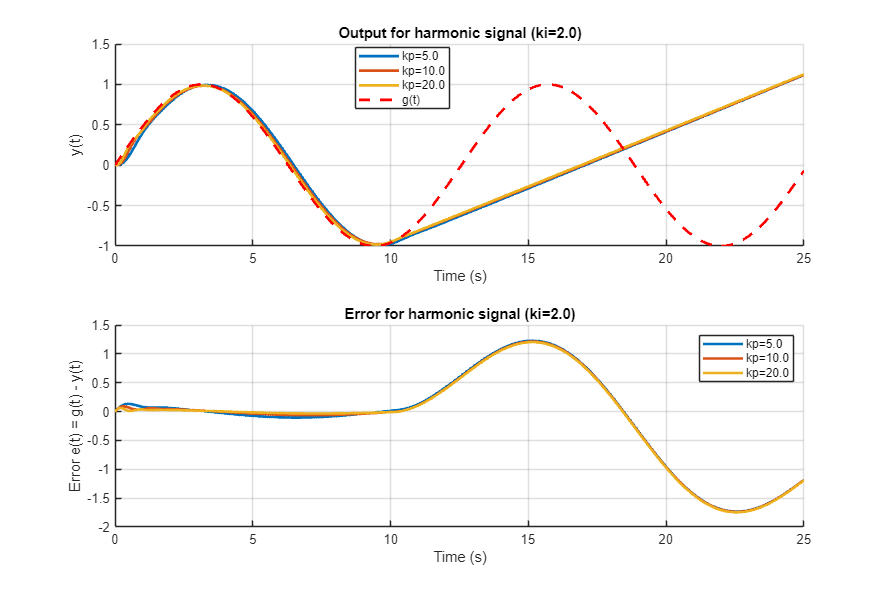

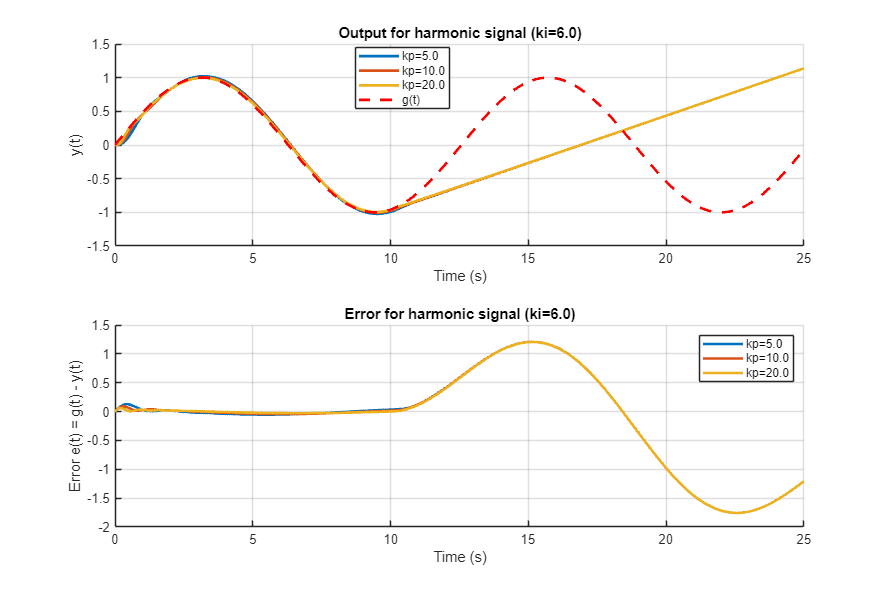

% Параметры системы
mdl = "task_5";
open_system(mdl);

A = 1; % Амплитуда
V = 2; % Скорость для линейного сигнала
omega = 0.5; % Частота для гармонического сигнала
t_end = 1000; % Время симуляции

% Параметры для симуляции
signal_types = {'linear', 'harmonic'};
kp_values = [5, 10, 20];
ki_values = [0.1, 2, 6];

% Цикл по типам сигналов
for signal_idx = 1:length(signal_types)
    signal_type = signal_types{signal_idx};

    % Создаём сигнал
    input_signal = generate_signal1(signal_type, ts, A, V, omega);

    % Цикл по значениям ki
    for ki = ki_values
        % Подготовка фигуры
        figure('Position', [100, 100, 900, 600]);
        legend_entries = {}; % Для легенды графиков
        
        % Цикл по значениям kp
        for kp = kp_values
            % Передача параметров в Simulink
            simIn = Simulink.SimulationInput(mdl);
            simIn = simIn.setVariable('input_signal', input_signal);
            simIn = simIn.setVariable('kp', kp);
            simIn = simIn.setVariable('ki', ki);

            % Установка времени симуляции в зависимости от типа сигнала
            switch signal_type
                case 'linear'
                    switch ki
                        case 0.1
                            t_end = 1000;
                        case 2
                            t_end = 50;
                        case 6
                            t_end = 10;
                    end
                case 'harmonic'
                    t_end = 25; % Время для гармонического сигнала
            end
            ts = linspace(0, t_end, 1000)';
            set_param(mdl, 'StopTime', num2str(t_end));

            % Запуск симуляции
            res = sim(simIn);

            % Извлечение данных
            sig = res.get('yout');
            time = sig{1}.Values.Time;
            y = sig{1}.Values.Data;

            % Расчёт ошибки e(t)
            g = generate_signal1(signal_type, time, A, V, omega);
            e = g(:, 2) - y;

            % Построение графика выхода y(t)
            subplot(2, 1, 1);
            hold on;
            plot(time, y, 'LineWidth', 2);
            legend_entries{end+1} = sprintf('kp=%.1f', kp);

            % Построение ошибки e(t)
            subplot(2, 1, 2);
            hold on;
            plot(time, e, 'LineWidth', 2);
        end

        % Настройки для первого подграфика - выход y(t)
        subplot(2, 1, 1);
        plot(time, g(:, 2), 'r--', 'LineWidth', 2); % Ожидаемый сигнал g(t)
        legend([legend_entries, {'g(t)'}], 'Location', 'best');
        xlabel('Time (s)');
        ylabel('y(t)');
        title(sprintf('Output for %s signal (ki=%.1f)', signal_type, ki));
        grid on;

        % Настройки для второго подграфика - ошибка e(t)
        subplot(2, 1, 2);
        legend(legend_entries, 'Location', 'best');
        xlabel('Time (s)');
        ylabel('Error e(t) = g(t) - y(t)');
        title(sprintf('Error for %s signal (ki=%.1f)', signal_type, ki));
        grid on;

        % Сохранение графика
        exportgraphics(gcf, sprintf('figs/task_5_out_%s_ki%.1f.png', signal_type, ki), 'Resolution', 300);
    end
end

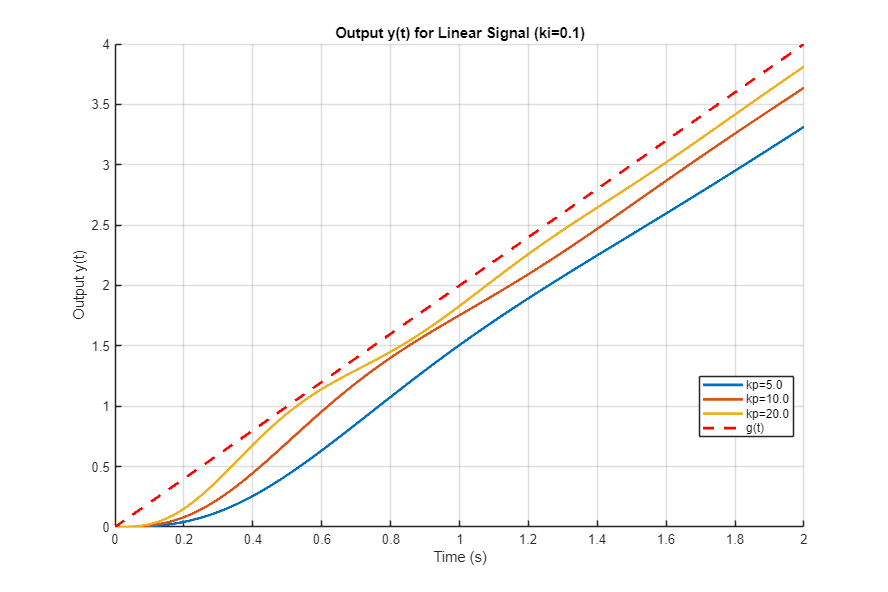

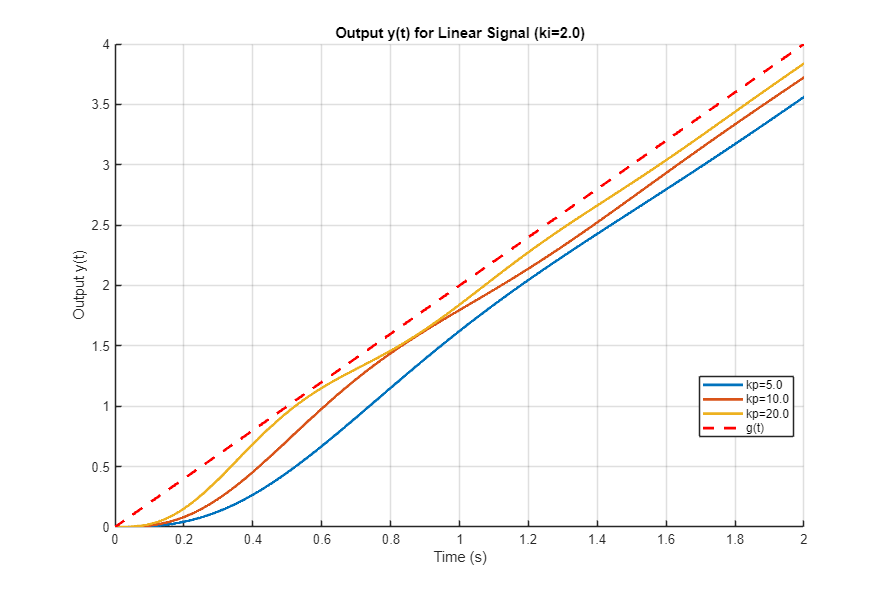

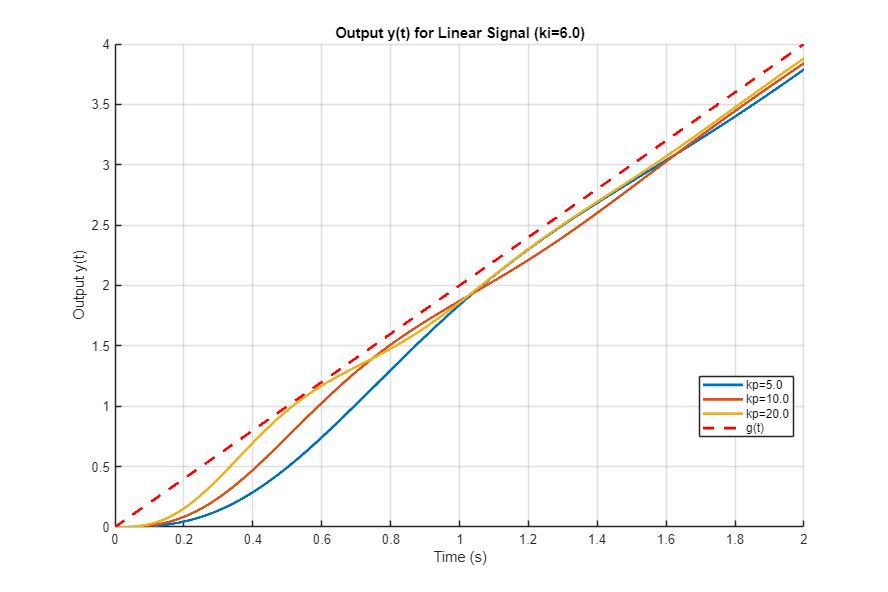

% Параметры для линейного сигнала
signal_type = 'linear';
A = 1;      % Не используется для линейного сигнала
V = 2;      % Скорость изменения сигнала
omega = 0.5; % Не используется для линейного сигнала
t_end = 2; % Рассматриваем малые значения времени
ts = linspace(0, t_end, 1000)'; % Временная шкала

% Генерация линейного сигнала
input_signal = generate_signal1(signal_type, ts, A, V, omega);

% Цикл по ki
for ki = ki_values
    % Подготовка фигуры для текущего ki
    figure('Position', [100, 100, 900, 600]);
    legend_entries = {}; % Для подписей легенды

    % Цикл по kp
    for kp = kp_values
        % Установка параметров kp и ki в Simulink
        simIn = Simulink.SimulationInput(mdl);
        simIn = simIn.setVariable('kp', kp);
        simIn = simIn.setVariable('ki', ki);
        simIn = simIn.setVariable('input_signal', input_signal);

        % Запуск симуляции
        res = sim(simIn);

        % Извлечение данных
        sig = res.get('yout');
        time = sig{1}.Values.Time;
        y = sig{1}.Values.Data;

        % Построение графика выхода y(t)
        hold on;
        plot(time, y, 'LineWidth', 2);
        legend_entries{end+1} = sprintf('kp=%.1f', kp);
    end

    % Добавление ожидаемого сигнала g(t)
    hold on;
    plot(ts, input_signal(:, 2), 'r--', 'LineWidth', 2, 'DisplayName', 'g(t)');

    % Настройки графика
    xlabel('Time (s)');
    ylabel('Output y(t)');
    title(sprintf('Output y(t) for Linear Signal (ki=%.1f)', ki));
    grid on;
    legend([legend_entries, {'g(t)'}], 'Location', 'best');
    xlim([0, t_end]); % Ограничение по времени

    % Сохранение графика
    exportgraphics(gcf, sprintf('figs/task_5_output_linear_small_t_ki_%.1f.png', ki), 'Resolution', 300);
end

## Задание 6. Задача слежения за гармоническим сигналом (регулятор общего вида)

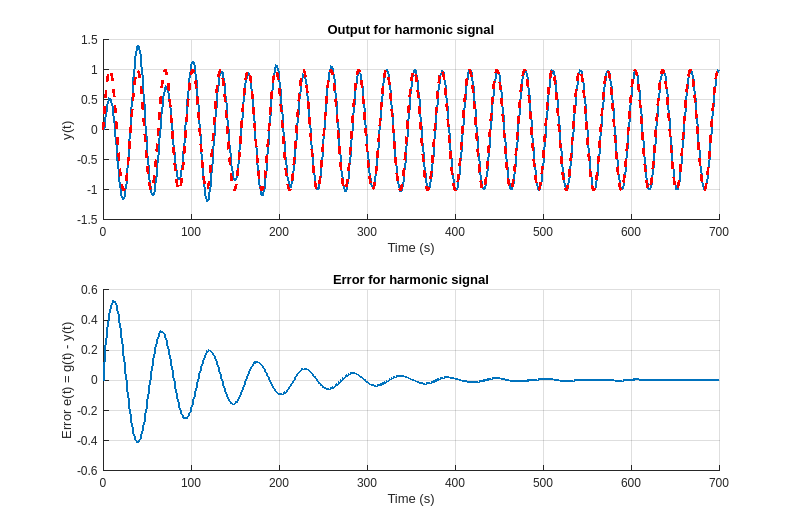

function signal = generate_signal2(type, t, A, V, omega)
    switch type
        case 'linear'
            signal = V * t;
        case 'harmonic'
            signal = A * sin(omega*t);
        otherwise
            error('Unknown signal type');
    end
    signal = [t, signal]; % Формат для передачи в Simulink
end

mdl = "task_6";
open_system(mdl);

% Параметры
A = 1;
V = 2;
omega=0.2;

% Параметры для симуляции
signal_types = {'harmonic'};

% Подготовка таблицы для сохранения установившихся значений (для линейного сигнала)
steady_state_table = [];

% Генерация и сохранение графиков для каждого типа сигнала
for signal_idx = 1:length(signal_types)
    signal_type = signal_types{signal_idx};
    
    % Установка времени симуляции в зависимости от типа сигнала
    switch signal_type
        case 'linear'
            t_end = 20; % Время для линейного сигнала
        case 'harmonic'
            t_end = 700; % Время для гармонического сигнала
    end
    ts = linspace(0, t_end, 1000)';

    % Установка времени симуляции в Simulink
    set_param(mdl, 'StopTime', num2str(t_end));

    % Создаем сигнал и передаем его в Simulink
    simIn = Simulink.SimulationInput(mdl);
    simIn = simIn.setVariable('input_signal', generate_signal2(signal_type, ts, A, V, omega));
    
    % Подготовка фигуры для графиков
    figure('Position', [0, 0, 900, 600]);
    
    % Цикл по всем комбинациям kp и ki
    legend_entries = {}; % Для легенды графиков
            
    % Запуск симуляции
    res = sim(simIn);
    
    % Извлекаем данные
    sig = res.get('yout');
    time = sig{1}.Values.Time;
    y = sig{1}.Values.Data;
    
    % Расчет ошибки e(t) = g(t) - y(t)
    g = generate_signal2(signal_type, time, A, V, omega);
    e = g(:, 2) - y; % Ошибка для второго графика

    % Настройки для первого подграфика - выход y(t)
    subplot(2, 1, 1);
    hold on;
    plot(time, y, 'LineWidth', 2);
    plot(g(:, 1), g(:, 2), 'r--', 'LineWidth', 2); % Ожидаемый сигнал g(t)
    xlabel('Time (s)');
    ylabel('y(t)');
    title(['Output for ', signal_type, ' signal']);
    grid on;
    
    % Настройки для второго подграфика - ошибка e(t)
    subplot(2, 1, 2);
    hold on;
    plot(time, e, 'LineWidth', 2);
    xlabel('Time (s)');
    ylabel('Error e(t) = g(t) - y(t)');
    title(['Error for ', signal_type, ' signal']);
    grid on;

    % Сохранение графика
    exportgraphics(gcf, ['figs/task_6_out_' signal_type '.png'], 'Resolution', 300);
end